#### First, we define some colours

c1=[0.5, 0.9, 0.1];
c2=[0.1, 0.6, 0.1];
c3=[0.1, 0.3, 0.1];

#### Plot of voltage behind transient reactance vs time

- voltage behind transient reactance (V_t)is not defined in the SVs as such.

- But we have the orthogonal components V_d and V_q as the last two SVs.

- We can easily get the magnitude of V_t form V_d and V_q.

- This code also saves the figure as a PNG file.

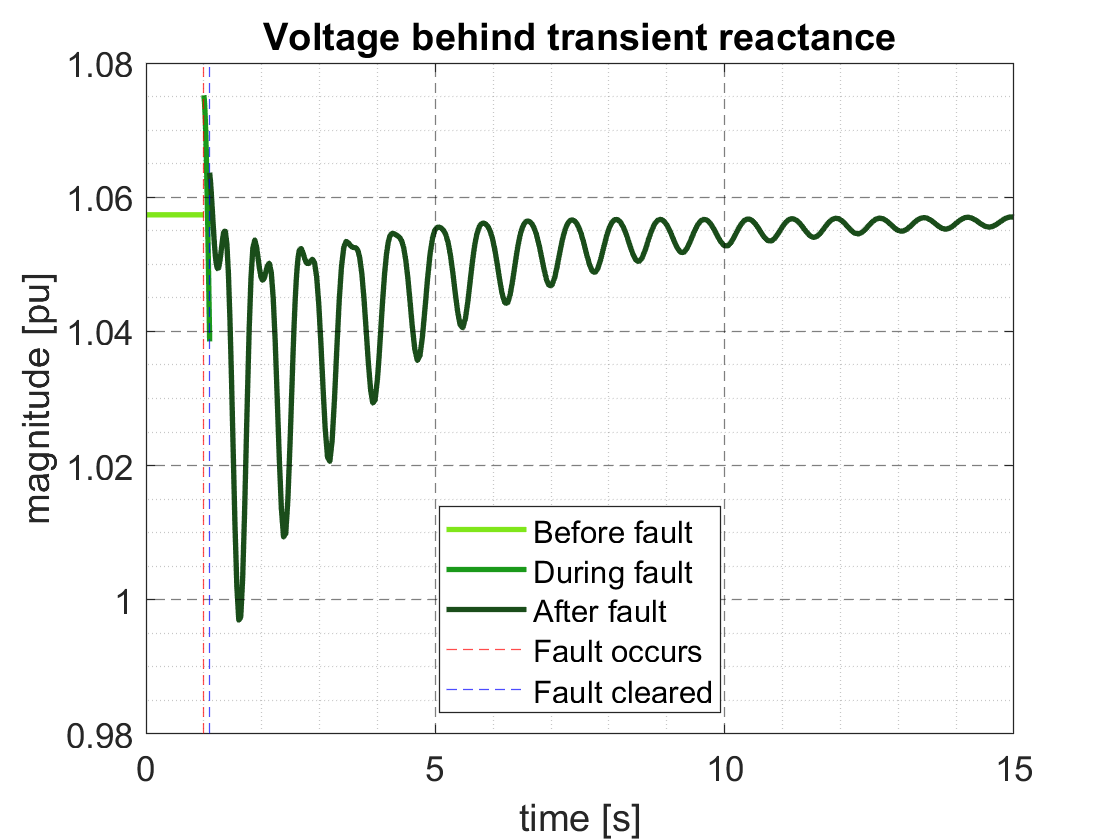

vt1=sqrt(x1(:,7).^2+x1(:,8).^2);
vt2=sqrt(x2(:,7).^2+x2(:,8).^2);
vt3=sqrt(x3(:,7).^2+x3(:,8).^2);
figure(1)
p1=plot(t1,vt1,'color',c1,'LineWidth',2);
hold on;
p2=plot(t2,vt2,'color',c2,'LineWidth',2);
hold on;
p3=plot(t3,vt3,'color',c3,'LineWidth',2);
hold on;
p4=xline(t1(end),'--r');
hold on;
p5=xline(t2(end),'--b');
hold on;
legend({'Before fault','During fault',...
    'After fault','Fault occurs',...
    'Fault cleared'...
    },'Location','south')
p1.Color(4) = 1.00;
p2.Color(4) = 1.00;
p3.Color(4) = 1.00;
grid on;
grid minor;
ax = gca;
ax.GridColor = [0.0000 0.0000 0.000];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
ax.Layer = 'top';
ax.FontSize = 13;
title('Voltage behind transient reactance');
%uncomment the next line for getting a closer look
%for during-fault conditions
%axis([0 1.5 0.995 1.078]);
xlabel('time [s]');
ylabel('magnitude [pu]');
filename=['smib_voltage_behind_transient_reactance_plot'];
saveas(gcf,filename,'png')
hold off;

#### Plot of delta vs time

- Delta values are defined as such in the SVs.

- This code also saves the figure as a PNG file.

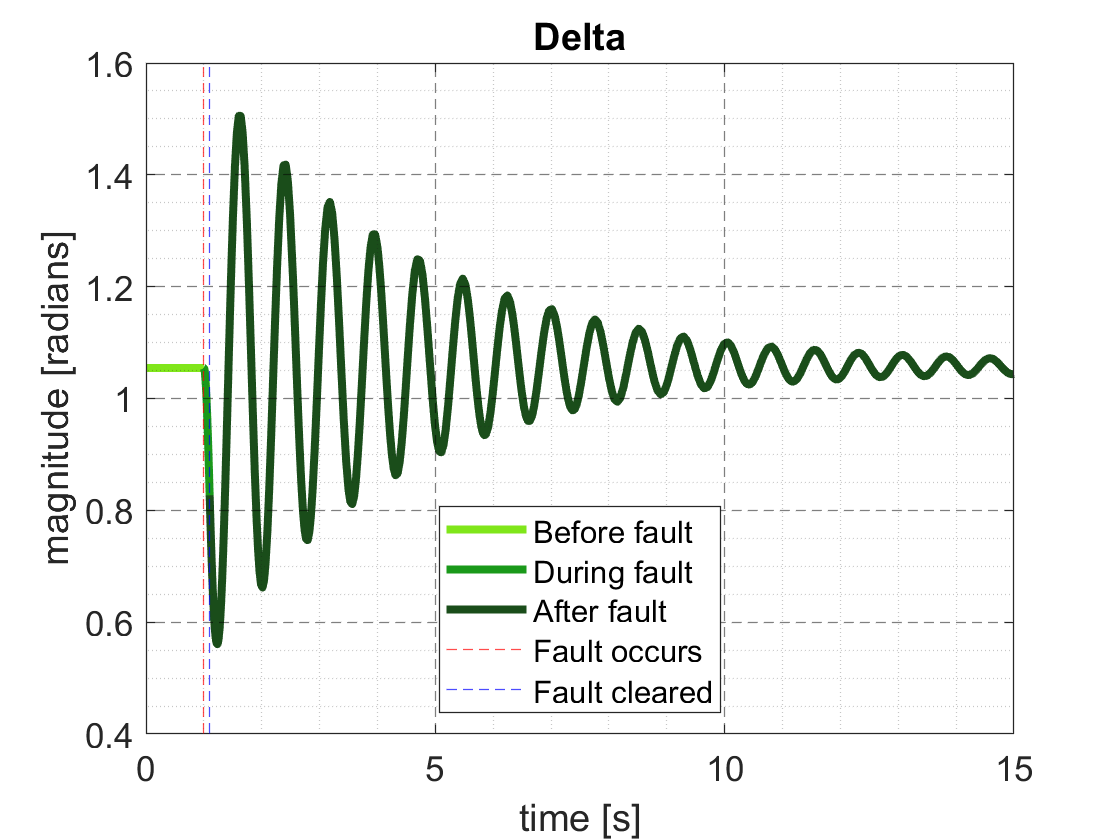

delta1=x1(:,3);
delta2=x2(:,3);
delta3=x3(:,3);
figure(2)
p1=plot(t1,delta1,'color',c1,'LineWidth',3);
hold on;
p2=plot(t2,delta2,'color',c2,'LineWidth',3);
hold on;
p3=plot(t3,delta3,'color',c3,'LineWidth',3);
hold on;
p4=xline(t1(end),'--r');
hold on;
p5=xline(t2(end),'--b');
hold on;
legend({'Before fault','During fault',...
    'After fault','Fault occurs','Fault cleared'...
    },'Location','south');
p1.Color(4) = 1.00;
p2.Color(4) = 1.00;
p3.Color(4) = 1.00;
grid on;
grid minor
ax = gca;
ax.GridColor = [0.0000 0.0000 0.000];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
ax.Layer = 'top';
ax.FontSize = 13;
title('Delta');
%uncomment the next line for getting a closer look
%for during-fault conditions
% axis([0 1.5 0.45 1.55]);
xlabel('time [s]');
ylabel('magnitude [radians]');
filename=['smib_delta_plot'];
saveas(gcf,filename,'png')